# A thin rolling wheel(NO slip) **- **Equations of motion via **Lagrange**

In this tutorial, we're going to use** Lagrange's method **to derive the equations of motion of a **thin wheel(or disk) that rolls along the ground**.  The Workflow that we'll adopt is summarised below:

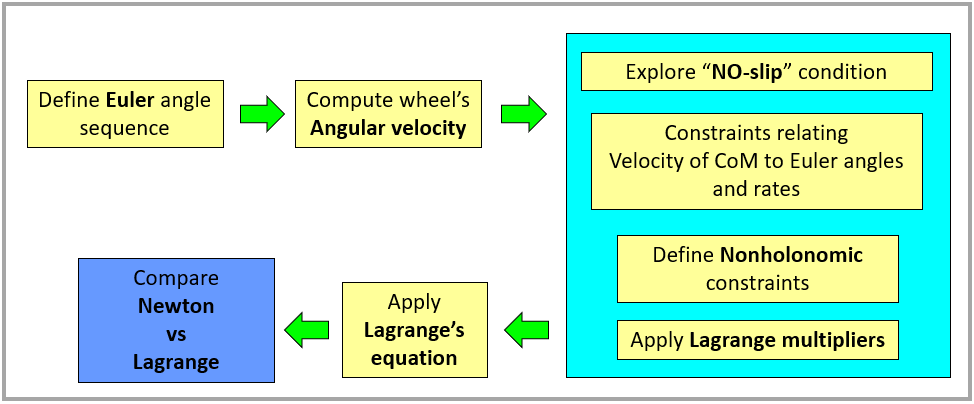

## The key concepts of the** Lagrangian formulation**:

Say we have an dynamic system described by the $\mathit{\mathbf{N}}$ **generalised co-ordinates**  $q_k =\left\lbrack \begin{array}{cccccc}
\phi  & \theta  & \psi  & x & y & z
\end{array}\right\rbrack$.  Say the system is subjected to $\mathit{\mathbf{P}}$ number of **constraints** of the form:

- $\;0\;\;=\;\sum_{k=1}^N \;A_{\textrm{jk}} \ldotp \delta q_k$     for    $j=1,2,\ldotp \ldotp \ldotp P$              

We can accumulate ALL of these $\mathit{\mathbf{P}}$** constraints **as :

- 
$$0\;\;=\;\;\;\sum_{j=1}^P \;\;\lambda_j \;\;\left(\sum_{k=1}^N A_{\textrm{jk}} \ldotp \delta q_k \right)\;\;=\;\sum_{j=1}^P \;\;\sum_{k=1}^N \lambda_j \;\ldotp \;A_{\textrm{jk}} \ldotp \;\delta q_k \;\;\;\;\;$$


where $\lambda_j$ represent Lagrange multipliers.  **Hamilton's principle** then leads to:

- 
$$\sum_{k=1}^N \left\lbrack \frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }\;-\;\;\;\;Q_k \;\;\;-\;\;\;\;\sum_{j=1}^P \;\;\lambda_j \;\;\ldotp A_{\textrm{jk}} \right\rbrack \ldotp \delta q_k \;\;\;\;=\;\;\;\;0$$


Which produces **Lagrange's equation** of the form:

-     $\frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }\;\;=\;\;\;\;Q_k \;\;\;\;+\;\;\;\;\sum_{j=1}^P \;\;\lambda_j \;\;\ldotp A_{\textrm{jk}}$           for    $q_k =\left\lbrack \begin{array}{cccccc}
\phi  & \theta  & \psi  & x & y & z
\end{array}\right\rbrack$

where:

- 
$$L=\textrm{KE}-\textrm{PE}$$


- $\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \;$represent the co-ordinates of the center of mass $G$ of the wheel in components of the inertial {E-frame}

-  $Q_k$ are the Generalised Forces for co-ordinate $q_k$

- there are $P$ number of constraints

- $A_{\textrm{jk}}$ represents the co-efficient of the term associated with $\delta q_k$ from the $j^{\textrm{th}}$ constraint equation written out in its variational form

- $\lambda_j$ represents the Lagrange multiplier associated with the $j^{\textrm{th}}$ constraint equation    

### The constraint equations:

We'll apply a **"NO slip" condition** that allows us to define 3 **nonholonomic  constraints** relating the INERTIAL velocity of the wheel's center of mass $G$ to the Euler angles and rates (these will be derived in this script):

- 
$$\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \;=\;\;\left\lbrack \begin{array}{c}
{\dot{X} }_G^E \\
{\dot{Y} }_G^E \\
{\dot{Z} }_G^E 
\end{array}\right\rbrack \;-\;\;\left(\begin{array}{c}
r\,{\left(\dot{\psi} \,\sin \left(\phi \right)+\dot{\theta} \,\cos \left(\phi \right)\,\cos \left(\theta \right)-\dot{\phi} \,\sin \left(\phi \right)\,\sin \left(\theta \right)\right)}\\
r\,{\left(\dot{\phi} \,\cos \left(\phi \right)\,\sin \left(\theta \right)-\dot{\psi} \,\cos \left(\phi \right)+\dot{\theta} \,\cos \left(\theta \right)\,\sin \left(\phi \right)\right)}\\
-r\,\dot{\theta} \,\sin \left(\theta \right)
\end{array}\right)$$


The variational forms of these constraints are:

- 
$$\begin{array}{l}
\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \;=\;\;\left\lbrack \begin{array}{c}
\delta X\\
\delta Y\\
\delta Z
\end{array}\right\rbrack \;-\;\;\left(\begin{array}{c}
r\,{\left(\delta \psi \ldotp \,\sin \left(\phi \right)+\,\delta \theta \ldotp \cos \left(\phi \right)\,\cos \left(\theta \right)-\delta \phi \ldotp \,\sin \left(\phi \right)\,\sin \left(\theta \right)\right)}\\
r\,{\left(\delta \phi \ldotp \,\cos \left(\phi \right)\,\sin \left(\theta \right)-\delta \psi \ldotp \,\cos \left(\phi \right)+\;\delta \theta \ldotp \,\cos \left(\theta \right)\,\sin \left(\phi \right)\right)}\\
-r\delta \theta \ldotp \sin \left(\theta \right)
\end{array}\right)\\
\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \;=\;\;r\ldotp \left\lbrack \begin{array}{cccccc}
\sin \left(\phi \right)\,\sin \left(\theta \right) & -\cos \left(\phi \right)\,\cos \left(\theta \right) & -\sin \left(\phi \right) & 1 & 0 & 0\\
-\cos \left(\phi \right)\,\sin \left(\theta \right) & -\cos \left(\theta \right)\,\sin \left(\phi \right) & \;\cos \left(\phi \right) & 0 & 1 & 0\\
0 & \sin \left(\theta \right) & 0 & 0 & 0 & 1
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\delta \phi \\
\delta \theta \\
\delta \psi \\
\delta X\\
\delta Y\\
\delta Z
\end{array}\right\rbrack \;\;=\;\;\;A\ldotp \left\lbrack \begin{array}{c}
\delta \phi \\
\delta \theta \\
\delta \psi \\
\delta X\\
\delta Y\\
\delta Z
\end{array}\right\rbrack 
\end{array}$$


The above variational constraints are absorbed into the Lagrangian equation AND the NO-slip condition also makes the generalised Forces $Q_K$ equate to zero.  The Lagrangian formulation that we'll be applying is summarised below:

- $\frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }\;\;=\;\;\sum_{j=1}^P \;\;\lambda_j \;\;\ldotp A_{\textrm{jk}}$            for       $q_k =\left\lbrack \begin{array}{cccccc}
\phi  & \theta  & \psi  & x & y & z
\end{array}\right\rbrack$

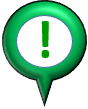  **NOTE:**  The application of the above Lagrange's equation, will give us 6 equations with the 9 unknowns $\left\lbrack \begin{array}{ccccccccc}
\ddot{\phi}  & \ddot{\theta}  & \ddot{\psi}  & \ddot{x}  & \ddot{y}  & \ddot{z}  & \lambda_1  & \lambda_2  & \lambda_3 
\end{array}\right\rbrack$.  To solve for these unknowns we need 3 more equations.  These 3 extra equations will come from computing the accelerations $\left\lbrack \begin{array}{ccc}
{\ddot{X} }_G^E  & {\ddot{Y} }_G^E  & {\ddot{Z} }_G^E 
\end{array}\right\rbrack$.

### Geometry and dimensions: 

The geometry and dimensions of the wheel are shown in Figure 1 below.

**Figure 1:  The thin wheel**

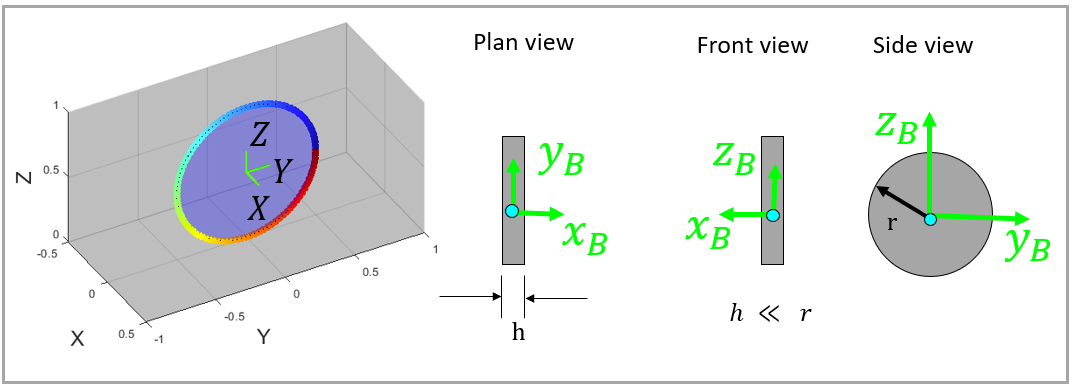

`Bradley Horton : 09-Nov-2020, bhorton@mathworks.com`

## Start with a clean slate

Clear any workspace varables

clc;  clear

## The Angular orientation of the wheel

Let's use 3 **Euler angles **to describe the wheel's angular orientation.  

- $R_{1Z}$ occurs  1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- $R_{2Y}$ occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- $R_{3X}$ occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can then express a vector defined in terms of the **Inertial {E-frame}** components , to it's corresponding components in a **body fixed {B-frame}**, using a sequence of **PASSIVE** rotation matrices, ie:

- 
$$v^B \;=\;\;\left\lbrack R_{3X} \left(\psi \right)\right\rbrack \;\ldotp \left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \;\ldotp \;\;v^E \;$$


This Euler angle sequence is illustrated below

     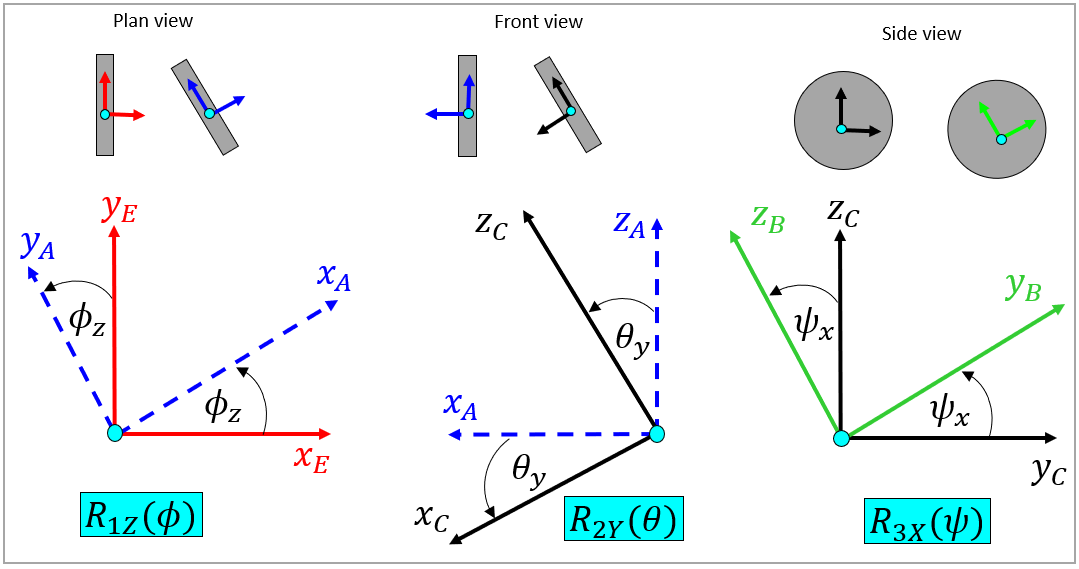   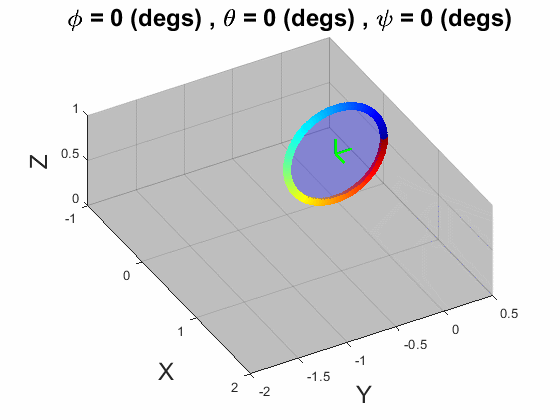

We'll use some symbolic variables to represent these **Euler angles and their rates **as well as some physical properties like mass and gravity

syms  m g r
syms  t 
syms  phi        theta        psi
syms  phi_dot    theta_dot    psi_dot
syms  phi_ddot   theta_ddot   psi_ddot
syms  PHI(t)     THETA(t)     PSI(t)   

Here are some symbols for representing the position of the center of mass $G$ of the wheel in the inertial {E-frame}

syms  x          y            z
syms  x_dot      y_dot        z_dot
syms  x_ddot     y_ddot       z_ddot
syms    X(t)         Y(t)       Z(t)   

And some lists of symbols:

% vars_pretty = [ phi        theta        psi,      ...
%                 phi_dot    theta_dot    psi_dot,  ...
%                 phi_ddot   theta_ddot   psi_ddot, ...
%                  x          y            z,       ...
%                  x_dot      y_dot        z_dot,   ...
%                  x_ddot     y_ddot       z_ddot                  ];
% 
% vars_actual = [      PHI(t)            THETA(t)            PSI(t)     , ...
%                 diff(PHI(t),t,1), diff(THETA(t),t,1), diff(PSI(t),t,1), ...
%                 diff(PHI(t),t,2), diff(THETA(t),t,2), diff(PSI(t),t,2), ...
%                        X(t)                Y(t)              Z(t)     , ...
%                   diff(X(t),t,1),     diff(Y(t),t,1),   diff(Z(t),t,1), ...
%                   diff(X(t),t,2),     diff(Y(t),t,2),   diff(Z(t),t,2)       ];    

vars_pretty = [ phi_ddot,   theta_ddot,   psi_ddot, ...
                phi_dot,    theta_dot,    psi_dot,  ...
                phi,        theta,        psi,      ...   
                x_ddot,     y_ddot,       z_ddot,   ...
                x_dot,      y_dot,        z_dot,    ...
                x,          y,            z         ...
             ];

vars_actual = [ diff(PHI(t),t,2), diff(THETA(t),t,2), diff(PSI(t),t,2), ...
                diff(PHI(t),t,1), diff(THETA(t),t,1), diff(PSI(t),t,1), ...
                          PHI(t),           THETA(t),           PSI(t), ...
                diff(X(t),t,2),     diff(Y(t),t,2),   diff(Z(t),t,2),   ...
                diff(X(t),t,1),     diff(Y(t),t,1),   diff(Z(t),t,1),   ...
                     X(t),               Y(t),             Z(t)         ...
                ];

# Exploring the constraints for the NO-slip condition

## The Angular velocity of the wheel

Let's use 3 Euler angles to describe the wheel's angular orientation.  The sequence that we'll use to relate a vector expressed in Inertial {E-frame} components , to it's corresponding components in a body fixed {B-frame}, is summarised below:

- 
$$v^B \;=\;\;\left\lbrack R_{3X} \left(\psi \right)\right\rbrack \;\ldotp \left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \;\ldotp \;\;v^E \;$$


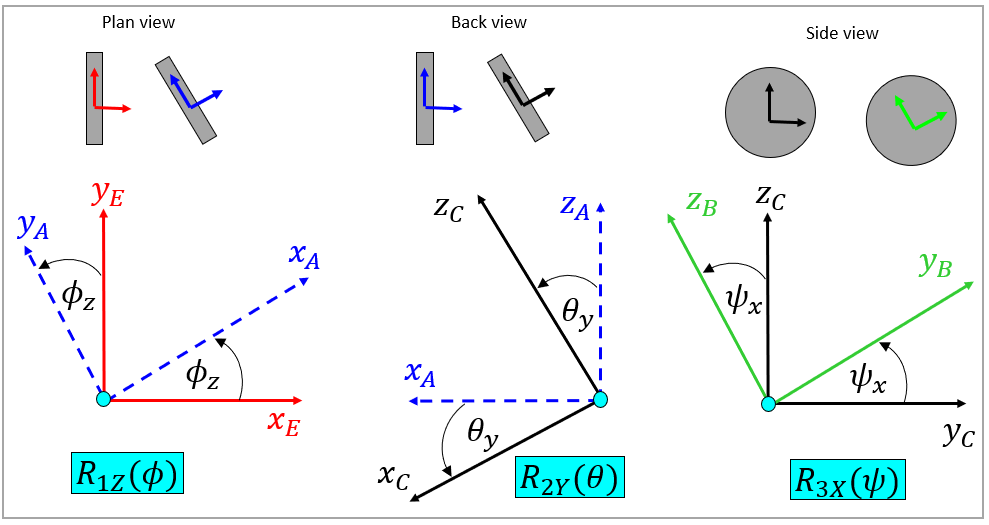

Corresponding to each frame rotation, are the associated angular velocities.  We can define these angular velocities initially in components of their local frames, 

- $\;\omega_{1Z}^A \;={\left\lbrack \begin{array}{ccc}
0 & 0 & \dot{\phi} 
\end{array}\right\rbrack }^T$    and     $\;\omega_{2Y}^C ={\left\lbrack \begin{array}{ccc}
0 & \dot{\theta}  & 0
\end{array}\right\rbrack }^T$   and     $\omega_{3X}^B ={\left\lbrack \begin{array}{ccc}
\dot{\psi}  & 0 & 0
\end{array}\right\rbrack }^T$

Let's compute the total angular velocity of the wheel and express it in components of the body fixed {B-frame}:

- 
$$\;\omega_{\textrm{WHEEL}}^B =\;\;R_X \left(\psi \right)\ldotp R_Y \left(\theta \right)\ldotp \omega_{1Z}^A \;\;\;\;\;\;+\;\;\;\;\;R_X \left(\psi \right)\ldotp \omega_{2Y}^C \;\;\;\;\;\;+\;\;\;\;\;\;\omega_{3X}^B$$


omega_B_wheel =  LOC_get_RX(psi)*LOC_get_RY(theta)*[0;0;phi_dot] + ...
                 LOC_get_RX(psi)*[0;theta_dot;0]                + ...
                 [psi_dot;0;0]

$$omega\_B\_wheel = \left(\begin{array}{c} \dot{\psi }-\dot{\varphi }\,\sin\left(\theta \right)\\ \dot{\theta }\,\cos\left(\psi \right)+\dot{\varphi }\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \dot{\varphi }\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\dot{\theta }\,\sin\left(\psi \right) \end{array}\right)$$

And we can convert the wheel's angular velocity into it's components in the {C-frame} via

- 
$${\omega_{\textrm{WHEEL}}^B \;=\;R}_X \left(\psi \right)\ldotp \omega_{\textrm{WHEEL}}^C$$
      
$$\Longrightarrow$$
     
$$\;\omega_{\textrm{WHEEL}}^C ={\left\lbrack {\;R}_X \left(\psi \right)\right\rbrack }^{-1} \;\ldotp \omega_{\textrm{WHEEL}}^B \;$$
   

omega_C_wheel = inv(LOC_get_RX(psi)) * omega_B_wheel;
omega_C_wheel = simplify(omega_C_wheel)

$$omega\_C\_wheel = \left(\begin{array}{c} \dot{\psi }-\dot{\varphi }\,\sin\left(\theta \right)\\ \dot{\theta }\\ \dot{\varphi }\,\cos\left(\theta \right) \end{array}\right)$$

The {C-frame} is significant because it allows us to apply the "no slip" condition.  Recall that the {C-frame} is a "semi fixed" frame (often referred to as a "shape" frame).  It's "semi fixed" because  $v^C \;\;=\;\left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \;\ldotp v^E$.  The full "body fixed" {B-frame} rotates relative to the {C-frame} via $v^B \;\;=\;\;\left\lbrack R_{3X} \left(\psi \right)\right\rbrack \;\;\ldotp v^C$.  

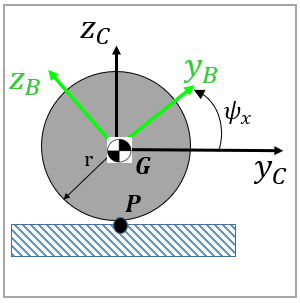

At the point where the wheel touches the ground we have:

-    
$$\begin{array}{l}
\;\;v_P^C =\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;v_G^C \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\;\;\;\;\;\;\omega_{\textrm{WHEEL}}^C \times r_P^C \;\;\\
\\
v_P^C \;=\;\left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \;\ldotp v_G^E \;\;\;\;+\;\;\;\omega_{\textrm{WHEEL}}^C \times r_P^C 
\end{array}$$
 
$$\;\;\;\;$$


Convert $v_G^E$ into it's components in the {C-frame}

syms X_dot_G__E   Y_dot_G__E   Z_dot_G__E  

v_G__E = [X_dot_G__E;   Y_dot_G__E;   Z_dot_G__E];
v_G__C = LOC_get_RY(theta) * LOC_get_RZ(phi) * v_G__E

$$v\_G\_\_C = \left(\begin{array}{c} {\dot{X}}_{G}^{E}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-{\dot{Z}}_{G}^{E}\,\sin\left(\theta \right)+{\dot{Y}}_{G}^{E}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ {\dot{Y}}_{G}^{E}\,\cos\left(\varphi \right)-{\dot{X}}_{G}^{E}\,\sin\left(\varphi \right)\\ {\dot{Z}}_{G}^{E}\,\cos\left(\theta \right)+{\dot{X}}_{G}^{E}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+{\dot{Y}}_{G}^{E}\,\sin\left(\varphi \right)\,\sin\left(\theta \right) \end{array}\right)$$

And compute the total velocity of point $P$

v_P__C = v_G__C  +  cross(omega_C_wheel, [0;0;-r])

$$v\_P\_\_C = \left(\begin{array}{c} {\dot{X}}_{G}^{E}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-{\dot{Z}}_{G}^{E}\,\sin\left(\theta \right)-r\,\dot{\theta }+{\dot{Y}}_{G}^{E}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ r\,\left(\dot{\psi }-\dot{\varphi }\,\sin\left(\theta \right)\right)+{\dot{Y}}_{G}^{E}\,\cos\left(\varphi \right)-{\dot{X}}_{G}^{E}\,\sin\left(\varphi \right)\\ {\dot{Z}}_{G}^{E}\,\cos\left(\theta \right)+{\dot{X}}_{G}^{E}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+{\dot{Y}}_{G}^{E}\,\sin\left(\varphi \right)\,\sin\left(\theta \right) \end{array}\right)$$

## Enforcing the NON-slip condition

For the NON-slip condition, we require that $0=\;v_P^C$  

tmp_EQ = 0 == v_P__C;

Enforcing the NON-slip condition then allows us to extract the constraints relating the velocity of the center of mass to the Euler angles and rates

tmp_sol    = solve(tmp_EQ, [X_dot_G__E;   Y_dot_G__E;   Z_dot_G__E]);
 
X_dot_G__E = simplify(tmp_sol.X_dot_G__E);
Y_dot_G__E = simplify(tmp_sol.Y_dot_G__E);
Z_dot_G__E = simplify(tmp_sol.Z_dot_G__E);

We now can express the velocity of the center of mass in terms of the Euler angles and rates

- 
$$\;v_G^E \;\;=f\left(\phi ,\theta ,\psi ,\dot{\phi} ,\dot{\theta} ,\dot{\psi} \right)\;$$


v_G__E = [   X_dot_G__E;
             Y_dot_G__E;
             Z_dot_G__E; ]

$$v\_G\_\_E = \left(\begin{array}{c} r\,\left(\dot{\psi }\,\sin\left(\varphi \right)+\dot{\theta }\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\dot{\varphi }\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\right)\\ r\,\left(\dot{\varphi }\,\cos\left(\varphi \right)\,\sin\left(\theta \right)-\dot{\psi }\,\cos\left(\varphi \right)+\dot{\theta }\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\right)\\ -r\,\dot{\theta }\,\sin\left(\theta \right) \end{array}\right)$$

 **SUNLIGHT test: ** We can write the velocity of point $P$ as:

- 
$$v_P^E =\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;v_G^E \;\;\;\;\;+\;\;\;\;\;\;{\left(\;\left\lbrack R_{2Y} \left(\theta \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\phi \right)\right\rbrack \right)}^{-1} \;\;\ldotp \left(\omega_{\textrm{WHEEL}}^C \times r_P^C \right)\;\;\;\;$$
 

Which we're expecting to be ZERO !

tmp_zero = v_G__E  + inv(LOC_get_RY(theta) * LOC_get_RZ(phi)) * cross(omega_C_wheel, [0;0;(-r)]);
tmp_zero = simplify(tmp_zero)

$$tmp\_zero = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

 **SUNLIGHT test(AGAIN): ** We can also write the velocity of point $P$ as:

- 
$$v_P^C =\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;v_G^C \;\;\;\;\;+\;\;\;\;\left(\omega_{\textrm{WHEEL}}^C \times r_P^C \right)\;\;\;\;$$


another_tmp_zero = LOC_get_RY(theta) * LOC_get_RZ(phi) * v_G__E  +  ...
                         cross(omega_C_wheel, [0;0;(-r)]);
another_tmp_zero = simplify( another_tmp_zero )

$$another\_tmp\_zero = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Good !

## **Summarising our NONholonmic constraints:**

The **nonholonomic** constraints relating the INERTIAL velocities to the Euler angles and rates is:

- 
$$\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \;=\;\;\left\lbrack \begin{array}{c}
{\dot{X} }_G^E \\
{\dot{Y} }_G^E \\
{\dot{Z} }_G^E 
\end{array}\right\rbrack \;-\;\;\left(\begin{array}{c}
r\,{\left(\dot{\psi} \,\sin \left(\phi \right)+\dot{\theta} \,\cos \left(\phi \right)\,\cos \left(\theta \right)-\dot{\phi} \,\sin \left(\phi \right)\,\sin \left(\theta \right)\right)}\\
r\,{\left(\dot{\phi} \,\cos \left(\phi \right)\,\sin \left(\theta \right)-\dot{\psi} \,\cos \left(\phi \right)+\dot{\theta} \,\cos \left(\theta \right)\,\sin \left(\phi \right)\right)}\\
-r\,\dot{\theta} \,\sin \left(\theta \right)
\end{array}\right)$$


We can convert these 3 constraint equations into the **variational form** by:

- multipling by $\textrm{dt}$

- replacing differental $\textrm{dq}$ with variational $\delta q$

- recoginsing that virtual displacements occur with time frozen ie $\textrm{dt}=0$

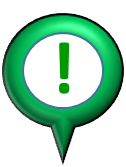Implementing these steps gives us:

- 
$$\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \;=\;\;\left\lbrack \begin{array}{c}
\delta X\\
\delta Y\\
\delta Z
\end{array}\right\rbrack \;-\;\;\left(\begin{array}{c}
r\,{\left(\delta \psi \ldotp \,\sin \left(\phi \right)+\,\delta \theta \ldotp \cos \left(\phi \right)\,\cos \left(\theta \right)-\delta \phi \ldotp \,\sin \left(\phi \right)\,\sin \left(\theta \right)\right)}\\
r\,{\left(\delta \phi \ldotp \,\cos \left(\phi \right)\,\sin \left(\theta \right)-\delta \psi \ldotp \,\cos \left(\phi \right)+\;\delta \theta \ldotp \,\cos \left(\theta \right)\,\sin \left(\phi \right)\right)}\\
-r\delta \theta \ldotp \sin \left(\theta \right)
\end{array}\right)$$


Let's automate this

syms delta_X delta_Y delta_Z  delta_phi  delta_theta  delta_psi

cons_EQ(1) = 0 == delta_X - subs(v_G__E(1), [phi_dot, theta_dot, psi_dot], [delta_phi  delta_theta  delta_psi]);
cons_EQ(2) = 0 == delta_Y - subs(v_G__E(2), [phi_dot, theta_dot, psi_dot], [delta_phi  delta_theta  delta_psi]);
cons_EQ(3) = 0 == delta_Z - subs(v_G__E(3), [phi_dot, theta_dot, psi_dot], [delta_phi  delta_theta  delta_psi]);

cons_EQ    = cons_EQ(:);

And we can put this into matrix form:

- $A\;\ldotp \;\delta q=0$     where     $\delta q\;={\left\lbrack \begin{array}{cccccc}
\delta \phi  & \delta \theta  & \delta \psi  & \delta X & \delta Y & \delta Z
\end{array}\right\rbrack }^T$

[cons_A, cons_b] = equationsToMatrix(cons_EQ, [delta_phi, delta_theta, delta_psi, delta_X, delta_Y, delta_Z ] )

$$cons\_A = \left(\begin{array}{cccccc} -r\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & r\,\cos\left(\varphi \right)\,\cos\left(\theta \right) & r\,\sin\left(\varphi \right) & -1 & 0 & 0\\ r\,\cos\left(\varphi \right)\,\sin\left(\theta \right) & r\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & -r\,\cos\left(\varphi \right) & 0 & -1 & 0\\ 0 & -r\,\sin\left(\theta \right) & 0 & 0 & 0 & -1 \end{array}\right)$$

$$cons\_b = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Next, let's multiply each constraint equation by a **Lagrange multiplier**:

syms  lambda_1   lambda_2    lambda_3

cons_A(1,:) = lambda_1 * cons_A(1,:);
cons_A(2,:) = lambda_2 * cons_A(2,:);
cons_A(3,:) = lambda_3 * cons_A(3,:);

cons_A

$$cons\_A = \left(\begin{array}{cccccc} -\lambda_{1}\,r\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & \lambda_{1}\,r\,\cos\left(\varphi \right)\,\cos\left(\theta \right) & \lambda_{1}\,r\,\sin\left(\varphi \right) & -\lambda_{1} & 0 & 0\\ \lambda_{2}\,r\,\cos\left(\varphi \right)\,\sin\left(\theta \right) & \lambda_{2}\,r\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & -\lambda_{2}\,r\,\cos\left(\varphi \right) & 0 & -\lambda_{2} & 0\\ 0 & -\lambda_{3}\,r\,\sin\left(\theta \right) & 0 & 0 & 0 & -\lambda_{3} \end{array}\right)$$

We'll be using this `cons_A` matrix in the next section.

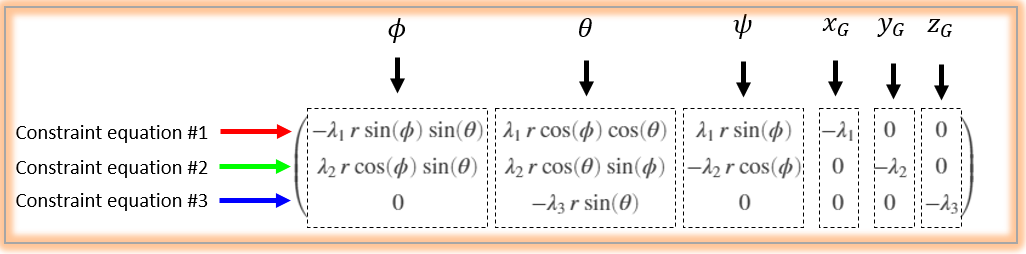

# A Lagrangian derivation

The equations of motion for the Rolling wheel with a NO-slip constraint can now be derived using Lagrange's technique.  The fundamental equation that we'll be using is:

-     $\frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }\;\;=\;\;\;\;Q_k \;\;\;\;+\;\;\;\;\sum_{j=1}^P \;\;\lambda_j \;\;\ldotp A_{\textrm{jk}}$             for    $q_k =\left\lbrack \begin{array}{cccccc}
\phi  & \theta  & \psi  & x & y & z
\end{array}\right\rbrack$

where:

- 
$$L=\textrm{KE}-\textrm{PE}$$


- $\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \;$represent the co-ordinates of the center of mass $G$ of the wheel in components of the inertial {E-frame}

-  $Q_k$ are the Generalised Forces for co-ordinate $q_k$

- $A_{\textrm{jk}}$ represents the co-efficient of the term associated with $\delta q_k$ from the $j^{\textrm{th}}$ constraint equation written out in its variational form

- $\lambda_j$ represents the Lagrange multiplier associatde with the $j^{\textrm{th}}$ constraint equation

 **NOTE:**  Regarding the system Generalised Forces $Q_k$, since the gravity force will be absorbed into the system $\textrm{PE}$ , the only active forces acting on the wheel are the reaction forces at the point of contact $P$ between the wheel and the ground.  However the NO-slip constraint means that the velocity at this point of contact is ZERO, ie: $0=v_P^C$, and hence the virtual work done by these contact forces is zero. So we do NOT need to compute $Q_k$ because it will be ZERO.

-  
$$Q_k \;\;\;=\;\;\;\sum_{i=1}^{{\textrm{Nf}}_{\textrm{nc}} } \left(\vec{F_i } \;\;\ldotp \;\frac{\partial \vec{v_i } }{\partial \dot{q_k } }\right)\;\;\;+\;\;\;\;\;\;\sum_{j=1}^{{N\tau }_{\textrm{nc}} } \left(\vec{\tau_j } \;\;\ldotp \;\frac{\partial \vec{\omega_j } }{\partial \dot{q_k } }\right)\;\;\;\;=\;\;\;\;\;\vec{F_P^C } \;\ldotp \frac{\partial \;\vec{v_P^C } }{\partial \dot{q_k } }\;\;\;=\;\;\;\vec{F_P^C } \;\ldotp 0\;\;\;=\;\;\;0\;$$


So the Lagangian equation that we'll construct and manipulate is just:

-   $\frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }\;\;\;\;\;\;\;=\;\;\;\;\;\;\;\;\;\sum_{j=1}^P \;\;\lambda_j \;\;\ldotp A_{\textrm{jk}}$         for    $q_k =\left\lbrack \begin{array}{cccccc}
\phi  & \theta  & \psi  & x & y & z
\end{array}\right\rbrack$

### Defining the system KE and PE:

Let's compute the system Kinetic and Potential energies:

- 
$$\textrm{KE}\;\;\;=\;\;\;\frac{1}{2}\ldotp m\ldotp \left(\;\;{\dot{X} }_E^G \;+\;{\dot{Y} }_E^G \;+\;{\dot{Z} }_E^G \;\;\right)\;\;\;\;+\;\;\;\frac{1}{2}\ldotp {\left\lbrack \omega_{\textrm{WHEEL}}^C \right\rbrack }^T \ldotp I_C^G \ldotp \;\omega_{\textrm{WHEEL}}^C$$


- 
$$\textrm{PE}\;\;\;\;=\;\;m\ldotp g\ldotp Z_G^E$$


syms I_A    % Axial       moment of Inertia  == I_xx
syms I_T    % Transverse  moment of Inertia  == I_yy == I_zz

I_mat   = [ I_A,     0,     0;
              0,   I_T,     0;
              0,     0,   I_T  ];

KE_trans =  0.5 * m * (x_dot^2  +  y_dot^2  +  z_dot^2);
KE_rot   = simplify( 0.5 * omega_B_wheel(:).' * I_mat * omega_B_wheel(:) );
KE       =  KE_trans  +  KE_rot;  

PE       =  m * g * z;

my_L     = simplify( KE - PE )

$$my\_L = \frac{I_{T}\,{\dot{\varphi }}^{2}}{2}+\frac{I_{A}\,{\dot{\psi }}^{2}}{2}+\frac{I_{T}\,{\dot{\theta }}^{2}}{2}+\frac{m\,\left({\dot{x}}^{2}+{\dot{y}}^{2}+{\dot{z}}^{2}\right)}{2}-g\,m\,z+\frac{I_{A}\,{\dot{\varphi }}^{2}\,{\sin\left(\theta \right)}^{2}}{2}-\frac{I_{T}\,{\dot{\varphi }}^{2}\,{\sin\left(\theta \right)}^{2}}{2}-I_{A}\,\dot{\varphi }\,\dot{\psi }\,\sin\left(\theta \right)$$

Now apply the LHS of Lagrange's equation:

- $\frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }$   we'll perform these computations in the subfunction `LOC_do_LHS_lag_eqn` 

-  **NOTE:**  we'll produce equations in the order  $q_k =\left\lbrack \begin{array}{cccccc}
\phi  & \theta  & \psi  & x & y & z
\end{array}\right\rbrack$

EOM_LHS(1) = LOC_do_LHS_lag_eqn(my_L, vars_actual, vars_pretty,  phi,   phi_dot);
EOM_LHS(2) = LOC_do_LHS_lag_eqn(my_L, vars_actual, vars_pretty,  theta, theta_dot); 
EOM_LHS(3) = LOC_do_LHS_lag_eqn(my_L, vars_actual, vars_pretty,  psi,   psi_dot); 
EOM_LHS(4) = LOC_do_LHS_lag_eqn(my_L, vars_actual, vars_pretty,  x,       x_dot);
EOM_LHS(5) = LOC_do_LHS_lag_eqn(my_L, vars_actual, vars_pretty,  y,       y_dot); 
EOM_LHS(6) = LOC_do_LHS_lag_eqn(my_L, vars_actual, vars_pretty,  z,       z_dot);  

EOM_LHS    = subs(EOM_LHS, vars_actual, vars_pretty);
EOM_LHS    = EOM_LHS(:);
EOM_LHS    = simplify(EOM_LHS)

$$EOM\_LHS = \left(\begin{array}{c} I_{A}\,\ddot{\varphi }-I_{A}\,\ddot{\psi }\,\sin\left(\theta \right)-I_{A}\,\ddot{\varphi }\,{\cos\left(\theta \right)}^{2}+I_{T}\,\ddot{\varphi }\,{\cos\left(\theta \right)}^{2}-I_{A}\,\dot{\psi }\,\dot{\theta }\,\cos\left(\theta \right)+I_{A}\,\dot{\varphi }\,\dot{\theta }\,\sin\left(2\,\theta \right)-I_{T}\,\dot{\varphi }\,\dot{\theta }\,\sin\left(2\,\theta \right)\\ I_{T}\,\ddot{\theta }-\frac{I_{A}\,{\dot{\varphi }}^{2}\,\sin\left(2\,\theta \right)}{2}+\frac{I_{T}\,{\dot{\varphi }}^{2}\,\sin\left(2\,\theta \right)}{2}+I_{A}\,\dot{\varphi }\,\dot{\psi }\,\cos\left(\theta \right)\\ -I_{A}\,\left(\ddot{\varphi }\,\sin\left(\theta \right)-\ddot{\psi }+\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)\right)\\ m\,\ddot{x}\\ m\,\ddot{y}\\ m\,\left(g+\ddot{z}\right) \end{array}\right)$$

Next, we need to compute the RHS of Lagrange's equation:

- $\frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }\;\;\;\;\;\;=\;\;\;\;\;\;\;\sum_{j=1}^P \;\;\lambda_j \;\;\ldotp A_{\textrm{jk}}$            for       $q_k =\left\lbrack \begin{array}{cccccc}
\phi  & \theta  & \psi  & x & y & z
\end{array}\right\rbrack$

Recall the `cons_A` matrix computed earlier.

EOM_RHS(1) = sum( cons_A(:,1) );
EOM_RHS(2) = sum( cons_A(:,2) );
EOM_RHS(3) = sum( cons_A(:,3) );
EOM_RHS(4) = sum( cons_A(:,4) );
EOM_RHS(5) = sum( cons_A(:,5) );
EOM_RHS(6) = sum( cons_A(:,6) );

EOM_RHS    = EOM_RHS(:);
EOM_RHS    = simplify(EOM_RHS)

$$EOM\_RHS = \left(\begin{array}{c} r\,\sin\left(\theta \right)\,\left(\lambda_{2}\,\cos\left(\varphi \right)-\lambda_{1}\,\sin\left(\varphi \right)\right)\\ r\,\left(\lambda_{1}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\lambda_{3}\,\sin\left(\theta \right)+\lambda_{2}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\right)\\ -r\,\left(\lambda_{2}\,\cos\left(\varphi \right)-\lambda_{1}\,\sin\left(\varphi \right)\right)\\ -\lambda_{1}\\ -\lambda_{2}\\ -\lambda_{3} \end{array}\right)$$

Now equate the LHS and RHS of Lagranges equation:

my_LAG_EQ = EOM_LHS == EOM_RHS

$$my\_LAG\_EQ = \left(\begin{array}{c} I_{A}\,\ddot{\varphi }-I_{A}\,\ddot{\psi }\,\sin\left(\theta \right)-I_{A}\,\ddot{\varphi }\,{\cos\left(\theta \right)}^{2}+I_{T}\,\ddot{\varphi }\,{\cos\left(\theta \right)}^{2}-I_{A}\,\dot{\psi }\,\dot{\theta }\,\cos\left(\theta \right)+I_{A}\,\dot{\varphi }\,\dot{\theta }\,\sin\left(2\,\theta \right)-I_{T}\,\dot{\varphi }\,\dot{\theta }\,\sin\left(2\,\theta \right)=r\,\sin\left(\theta \right)\,\left(\lambda_{2}\,\cos\left(\varphi \right)-\lambda_{1}\,\sin\left(\varphi \right)\right)\\ I_{T}\,\ddot{\theta }-\frac{I_{A}\,{\dot{\varphi }}^{2}\,\sin\left(2\,\theta \right)}{2}+\frac{I_{T}\,{\dot{\varphi }}^{2}\,\sin\left(2\,\theta \right)}{2}+I_{A}\,\dot{\varphi }\,\dot{\psi }\,\cos\left(\theta \right)=r\,\left(\lambda_{1}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\lambda_{3}\,\sin\left(\theta \right)+\lambda_{2}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\right)\\ -I_{A}\,\left(\ddot{\varphi }\,\sin\left(\theta \right)-\ddot{\psi }+\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)\right)=-r\,\left(\lambda_{2}\,\cos\left(\varphi \right)-\lambda_{1}\,\sin\left(\varphi \right)\right)\\ m\,\ddot{x}=-\lambda_{1}\\ m\,\ddot{y}=-\lambda_{2}\\ m\,\left(g+\ddot{z}\right)=-\lambda_{3} \end{array}\right)$$

### Generating the extra 3 equations:

What we have above are 6 equations with 9 unknowns, ie:  $\left\lbrack \begin{array}{ccccccccc}
\ddot{\phi}  & \ddot{\theta}  & \ddot{\psi}  & \ddot{x}  & \ddot{y}  & \ddot{z}  & \lambda_1  & \lambda_2  & \lambda_3 
\end{array}\right\rbrack$.   We need 3 more equations to help us solve for the 9 unknowns.  We can generate these extra 3 equations by using the velocity equations for $v_G^E$ and differentiating them (because we want terms involving $\ddot{\phi} ,\;\;\ddot{\theta} \;\;,\;\ddot{\psi}$).

tmp_A_XYZ   = diff( subs(v_G__E,    vars_pretty, vars_actual), t   );
tmp_A_XYZ   =       subs(tmp_A_XYZ, vars_actual, vars_pretty);

my_EQ_A_XYZ = [x_ddot;y_ddot;z_ddot] == tmp_A_XYZ(:);

Now combine these 3 additional equations with the original 6 equations:

my_LAG_EQ = [ my_LAG_EQ; 
              my_EQ_A_XYZ ]

 We now have 9 equations with 9 unknowns.  To solve for the unknowns we'll assemble a system of equations of the form:

-  $A\ldotp q=b$   where    $q={\left\lbrack \begin{array}{ccccccccc}
\ddot{\phi}  & \ddot{\theta}  & \ddot{\psi}  & \ddot{x}  & \ddot{y}  & \ddot{z}  & \lambda_1  & \lambda_2  & \lambda_3 
\end{array}\right\rbrack }^T$

[my_sol_A, my_sol_b] = equationsToMatrix( my_LAG_EQ, ...
                                          [phi_ddot   theta_ddot   psi_ddot, ...
                                             x_ddot       y_ddot     z_ddot, ...
                                             lambda_1, lambda_2, lambda_3] )

$$my\_sol\_A = \left(\begin{array}{ccccccccc} I_{A}-I_{A}\,{\cos\left(\theta \right)}^{2}+I_{T}\,{\cos\left(\theta \right)}^{2} & 0 & -I_{A}\,\sin\left(\theta \right) & 0 & 0 & 0 & r\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & -r\,\cos\left(\varphi \right)\,\sin\left(\theta \right) & 0\\ 0 & I_{T} & 0 & 0 & 0 & 0 & -r\,\cos\left(\varphi \right)\,\cos\left(\theta \right) & -r\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & r\,\sin\left(\theta \right)\\ -I_{A}\,\sin\left(\theta \right) & 0 & I_{A} & 0 & 0 & 0 & -r\,\sin\left(\varphi \right) & r\,\cos\left(\varphi \right) & 0\\ 0 & 0 & 0 & m & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & m & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & m & 0 & 0 & 1\\ r\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & -r\,\cos\left(\varphi \right)\,\cos\left(\theta \right) & -r\,\sin\left(\varphi \right) & 1 & 0 & 0 & 0 & 0 & 0\\ -r\,\cos\left(\varphi \right)\,\sin\left(\theta \right) & -r\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & r\,\cos\left(\varphi \right) & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & r\,\sin\left(\theta \right) & 0 & 0 & 0 & 1 & 0 & 0 & 0 \end{array}\right)$$

$$my\_sol\_b = \left(\begin{array}{c} I_{A}\,\dot{\psi }\,\dot{\theta }\,\cos\left(\theta \right)-I_{A}\,\dot{\varphi }\,\dot{\theta }\,\sin\left(2\,\theta \right)+I_{T}\,\dot{\varphi }\,\dot{\theta }\,\sin\left(2\,\theta \right)\\ \frac{I_{A}\,{\dot{\varphi }}^{2}\,\sin\left(2\,\theta \right)}{2}-\frac{I_{T}\,{\dot{\varphi }}^{2}\,\sin\left(2\,\theta \right)}{2}-I_{A}\,\dot{\varphi }\,\dot{\psi }\,\cos\left(\theta \right)\\ I_{A}\,\dot{\varphi }\,\dot{\theta }\,\cos\left(\theta \right)\\ 0\\ 0\\ -g\,m\\ -r\,\left(\cos\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\varphi }}^{2}+2\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\dot{\varphi }\,\dot{\theta }-\dot{\psi }\,\cos\left(\varphi \right)\,\dot{\varphi }+\cos\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}\right)\\ r\,\left(-\sin\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\varphi }}^{2}+2\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\dot{\varphi }\,\dot{\theta }+\dot{\psi }\,\sin\left(\varphi \right)\,\dot{\varphi }-\sin\left(\varphi \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}\right)\\ -r\,{\dot{\theta }}^{2}\,\cos\left(\theta \right) \end{array}\right)$$

##  Create a Simulink block of our equations

In the next tutorial, we're going to simulate the dynamics that we've just derived, i.e. we'll specify numeric values for our wheel parameters (e.g.:  $r,m,I_{\textrm{XX}} ,I_{\textrm{YY}}$  etc) and we'll numerically solve the non linear ODEs derived above.  Although we could perform this simulation in MATLAB, there is another (even easier) way - it's called Simulink.  But in order to use Simulink we need a way of importing our derived equations of motion.  Rather than writing out by hand the derived equations, we'll use the [`matlabFunctionBlock()`](matlab:  web(fullfile(docroot, 'symbolic/matlabfunctionblock.html'))) function to automatically convert these equations into a MATLAB Function block.  Conceptually we're going to perform the task shown below:

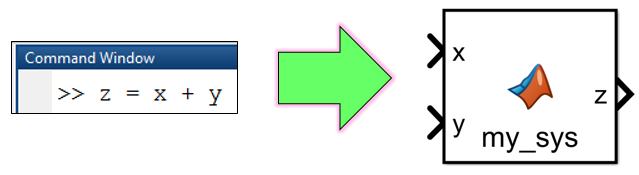     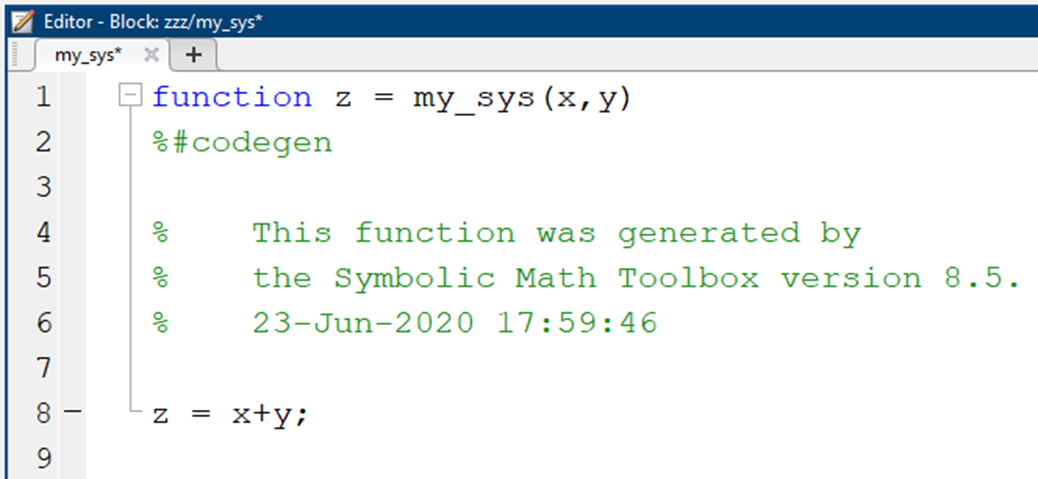

tf_i_should_create_SL_block = true;

if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_Ab_LAG_rolling';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
    
    %-------------------------------------------------------
    % Create a block that computes A and b
    matlabFunctionBlock( [MODEL_NAME,'/my_A_and_b_Lagrange'], ...
                         my_sol_A,    my_sol_b,  ...
                        'Outputs',  {'A', 'b'},  ...
                        'Optimize', false );
                    
    % make the block a YELLOW color
    set_param([MODEL_NAME,'/my_A_and_b_Lagrange'],'BackgroundColor','[1, 1, 0.607843]')
end

# **Next Steps**

We'll compare the results of this Lagrangian derivation against the Newtonian derivation.  The comparison will be done running the Simulink model launched by the script file:

- [`bh_DEMO_03_rolling_wheel_Simulation`](matlab:  edit bh_DEMO_03_rolling_wheel_Simulation)

              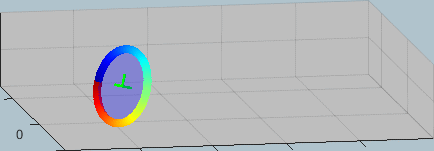

Also if you're interested we'll compare directly(ie analytically) the Lagrangian and Newtonian derivations in the next section below.

# **BONUS:  **Comparing analytically Lagrange vs Newton

Given that we've previously derived the equations of motion for this system using Newton's method([`bh_DEMO_01_rolling_wheel_Newton`](matlab: edit bh_DEMO_01_rolling_wheel_Newton)), I'm curious if we can simplify our Lagrangian equations and get "identical" analytic expressions for $\left\lbrack \begin{array}{ccc}
\ddot{\phi}  & \ddot{\theta}  & \ddot{\psi} 
\end{array}\right\rbrack$ that we produced using Newton's method.  So .... let's revisit the the 9 Lagrangian equations that we presented earlier, ie: the equations in the variable `my_LAG_EQ `.... and let's see what we can do:

my_LAG_EQ

So looking carefully at these 9 equations we see that:

- 
$$\textrm{EQ}\_\textrm{#9}\;\;\Longrightarrow \;\;\ddot{z} =f\left(\theta ,\dot{\theta} ,\ddot{\theta} \right)$$


- 
$$\textrm{EQ}\_\textrm{#8}\;\;\Longrightarrow \;\;\ddot{y} =g\left(\phi ,\dot{\phi} ,\ddot{\phi} ,\;\;\theta ,\dot{\theta} ,\ddot{\theta} \;\;,\dot{\psi} ,\ddot{\psi} \right)$$


- 
$$\textrm{EQ}\_\textrm{#7}\;\;\Longrightarrow \;\;\ddot{x} =h\left(\phi ,\dot{\phi} ,\ddot{\phi} ,\;\;\theta ,\dot{\theta} ,\ddot{\theta} \;\;,\dot{\psi} ,\ddot{\psi} \right)$$


- 
$$\textrm{EQ}\_\textrm{#6}\;\;\Longrightarrow \lambda_3 =F\left(\ddot{z} \right)$$


- 
$$\textrm{EQ}\_\textrm{#5}\;\;\Longrightarrow \lambda_2 =G\left(\ddot{y} \right)$$


- 
$$\textrm{EQ}\_\textrm{#4}\;\;\Longrightarrow \lambda_1 =H\left(\ddot{x} \right)$$


So it feels like we can express the Lagrange multipliers $\lambda_1 ,\lambda_2 ,\lambda_3$ as functions of our Euler angles  .... and then substitute these expressions into the first 3 equations.  This would give us 3 equations ONLY containing Euler angle parameters ... which we can then use to solve for $\left\lbrack \begin{array}{ccc}
\ddot{\phi}  & \ddot{\theta}  & \ddot{\psi} 
\end{array}\right\rbrack$ ..... and then we could compare these expressions to those derived using Newton's method.  Let's try it:

tmp_zDD      = rhs(my_LAG_EQ(9));
tmp_yDD      = rhs(my_LAG_EQ(8));
tmp_xDD      = rhs(my_LAG_EQ(7));

tmp_LAMBDA_3 = -1*m*(g + tmp_zDD);
tmp_LAMBDA_2 = -1*m*tmp_yDD;
tmp_LAMBDA_1 = -1*m*tmp_xDD;

tmp_EQ1      = subs(my_LAG_EQ(1), [lambda_1, lambda_2, lambda_3], [tmp_LAMBDA_1, tmp_LAMBDA_2, tmp_LAMBDA_3]);
tmp_EQ2      = subs(my_LAG_EQ(2), [lambda_1, lambda_2, lambda_3], [tmp_LAMBDA_1, tmp_LAMBDA_2, tmp_LAMBDA_3]);
tmp_EQ3      = subs(my_LAG_EQ(3), [lambda_1, lambda_2, lambda_3], [tmp_LAMBDA_1, tmp_LAMBDA_2, tmp_LAMBDA_3]);

tmp_sol      = solve([tmp_EQ1;tmp_EQ2;tmp_EQ3], [phi_ddot, theta_ddot, psi_ddot]);
tmp_vec_sol  = simplify([tmp_sol.phi_ddot; tmp_sol.theta_ddot; tmp_sol.psi_ddot]);

So what do the expressions for $\left\lbrack \begin{array}{ccc}
\ddot{\phi}  & \ddot{\theta}  & \ddot{\psi} 
\end{array}\right\rbrack$ look like :

tmp_vec_sol

$$tmp\_vec\_sol = \left(\begin{array}{c} \frac{\dot{\theta }\,\left(I_{A}\,\dot{\psi }-I_{A}\,\dot{\varphi }\,\sin\left(\theta \right)+2\,I_{T}\,\dot{\varphi }\,\sin\left(\theta \right)\right)}{I_{T}\,\cos\left(\theta \right)}\\ \frac{I_{A}\,{\dot{\varphi }}^{2}\,\sin\left(2\,\theta \right)-I_{T}\,{\dot{\varphi }}^{2}\,\sin\left(2\,\theta \right)-2\,I_{A}\,\dot{\varphi }\,\dot{\psi }\,\cos\left(\theta \right)+2\,g\,m\,r\,\sin\left(\theta \right)+m\,{\dot{\varphi }}^{2}\,r^{2}\,\sin\left(2\,\theta \right)-2\,m\,\dot{\varphi }\,\dot{\psi }\,r^{2}\,\cos\left(\theta \right)}{2\,\left(m\,r^{2}+I_{T}\right)}\\ \frac{\dot{\theta }\,\left(-\dot{\varphi }\,{I_{A}}^{2}\,{\sin\left(\theta \right)}^{2}+\dot{\psi }\,{I_{A}}^{2}\,\sin\left(\theta \right)-m\,\dot{\varphi }\,I_{A}\,r^{2}\,{\sin\left(\theta \right)}^{2}+m\,\dot{\psi }\,I_{A}\,r^{2}\,\sin\left(\theta \right)+I_{T}\,\dot{\varphi }\,I_{A}\,{\sin\left(\theta \right)}^{2}+I_{T}\,\dot{\varphi }\,I_{A}+2\,I_{T}\,m\,\dot{\varphi }\,r^{2}\right)}{I_{T}\,\cos\left(\theta \right)\,\left(m\,r^{2}+I_{A}\right)} \end{array}\right)$$

Compare the above results against the equations derived in the script file [`bh_rolling_wheel_Newton.mlx`](matlab:  edit bh_rolling_wheel_Newton.mlx)

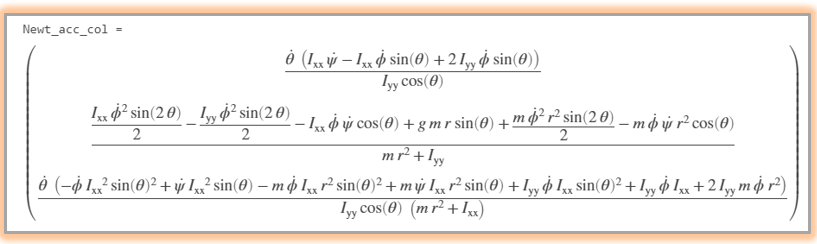

**CONCLUSION:  **

- The two sets of equations are identical (NOTE:  $I_A ==I_{\textrm{xx}} \;\;\;\textrm{and}\;I_T ==I_{\textrm{yy}}$).  

- So this is VERY reassuring - we get the same equations of motion using both the Newtonian and Lagrangian approaches !

- When we run our Simulink model that numerically solves the Lagrangian equation set(9 equations) AND the Newton equation set(3 equations) .... we really are expecting the simulation results to be identical.

# Local Subfunctions only beyond this point

Hello 

Define the passive Rotation matrix - $R_X \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_X \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RX(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1X'}, a, 'SYM');
    R   = OBJ.get_R;
end

Define the passive Rotation matrix - $R_Y \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_Y \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RY(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1Y'}, a, 'SYM');
    R   = OBJ.get_R;
end

Define the passive Rotation matrix - $R_Z \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_Z \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RZ(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1Z'}, a, 'SYM');
    R   = OBJ.get_R;
end

Implement the LHS of Lagranges equation for a single generalise co-ordinate, i.e. compute the following:

- 
$$\frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }\;$$


function EOM_LHS = LOC_do_LHS_lag_eqn(L_ORIGINAL, actual_list, pretty_list, q, q_dot)
    syms t

    L                 = subs(L_ORIGINAL,  actual_list, pretty_list);
    dLdqdot           = diff(L,       q_dot);
    dLdqdot           = subs(dLdqdot,  pretty_list, actual_list);    
    der_dt_of_dLdqdot = diff(dLdqdot, t);
    dLdq              = diff(L, q);
    dLdq              = subs(dLdq,    pretty_list, actual_list);
    
    EOM_LHS           = der_dt_of_dLdqdot - dLdq;
    EOM_LHS           = simplify( EOM_LHS );
end